# Conception d'un observateur d'état

clearvars

## Introduction :

**But ?**

Estimer des variables d'état du système pour le **surveiller** ou le **contrôler**.

**Pourquoi ?**

Mesurer les variables du vecteur d'état peut être problématique :

- **coût** du capteur, de son conditionneur ou de sa maintenance

- **contrainte** de design (ex : encombrement)

- technologie **inexistante**

- capteurs de **qualité médiocre** ont souhaite alors augmenter leur performance (réduire le bruit, supprimer le biais de mesure, retirer les valeurs abérentes...)

**Principe ?**

- On va utiliser le **simuler le modèle en parallèle** du système réel avec le même signal de commande

- On va **réajuster l'état de la simulation** si on a un **écart** entre la simulation et la mesure du issue de système

## Construction d'un observateur d'état

Un observateur est système dynamique **complétement artificiel.** Il fait partie du correcteur/superviseur du système. Par exemple dans le cas de notre robot de TP, il sera réalisé dans le code de l'Arduino.

### Mise en place d'une simulation en parallèle du système


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}
\end{array}$$


avec $x$ le vecteur d'état du **système **et $y$ **les mesures** issues des capteurs.

A=[-1 0;1 0]; B=[1;0]; C=[0 1];

**On suppose que les matrices **$A,B$** et **$C$** sont parfaitement connues**. On peut construire une simulation de notre système qui nous donne à la fois une estimation des sorties du système et de son état interne :


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\hat{x} =A\hat{x} +\textrm{Bu}\\
\hat{y} =C\hat{x} 
\end{array}$$
 

où $\hat{x}$ est une estimation du vecteur d'état du **système **et $\hat{y}$ une estimation de ce que l'on devrait mesurer au niveau des capteurs. 

*Rq : on injecte le signal de commande du système, on utilise les mêmes matrices que celles du modèle du système.* 

Ao=A; Bo=B; Co=C;

En plaçant ces deux systèmes en parallèle on obtient le résultat suivant :

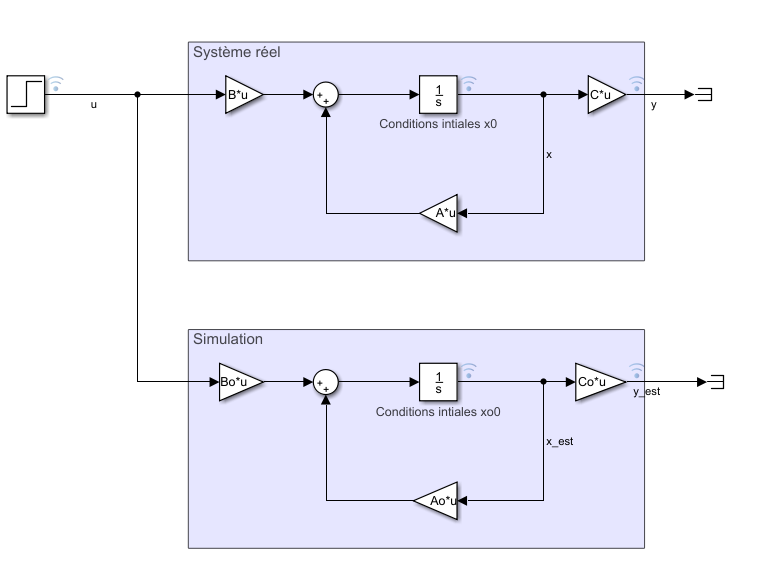

*Rq : Attention pour pouvoir réaliser ces schémas, les gains doivent être configurés pour réaliser des multiplications matricelles (par défaut c'est éléments par éléments) *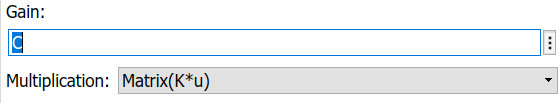

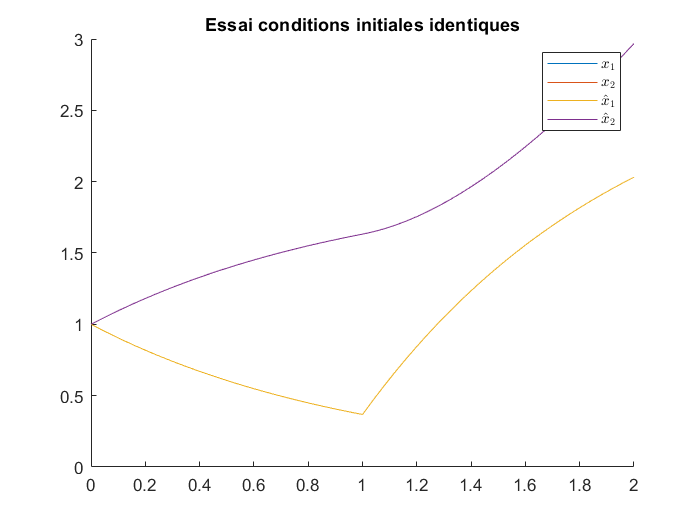

x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   x0;

figure, clf, hold all

out = sim('Observateur_step1.slx');
plot(out.logsout.find('x').Values)
plot(out.logsout.find('x_est').Values)
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')
title('Essai conditions initiales identiques')

On peut voir que l'observateur estime parfaitement l'état du système. Mais on a triché... Il faut vérifier ce qui se passe pour des conditions initiales erronées.

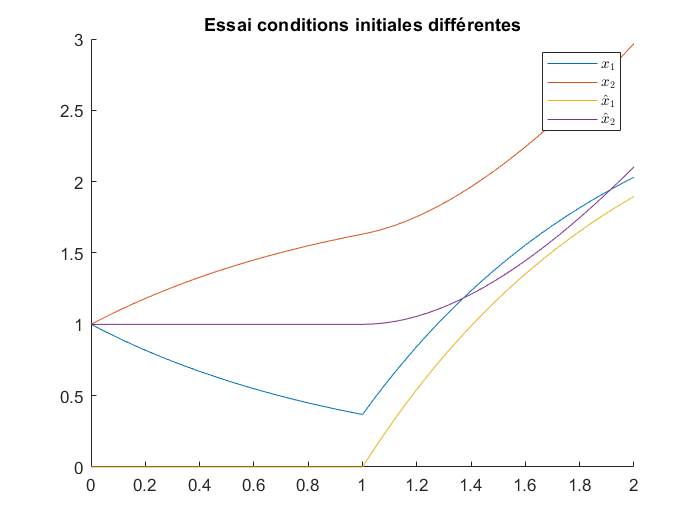

x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 1];

figure, clf, hold all

out = sim('Observateur_step1.slx');
plot(out.logsout.find('x').Values)
plot(out.logsout.find('x_est').Values)
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')
title('Essai conditions initiales différentes')

Si les conditions initiales de l'observateur ne sont pas celles du système, cela ne fonctionne pas. On cherche donc un moyen de faire converger l'erreur d'observation $x-\hat{x}$  vers 0 en se basant uniquement sur les mesures $y$. 

Pour cela on va modifier $\hat{x}$ en ajoutant à $\frac{d}{\textrm{dt}}\hat{x}$ une fonction de l'erreur de sortie$y-\hat{y}$. On appelle cette structure un observateur de Luenberger.

### Observateur de Luenberger

#### Structure

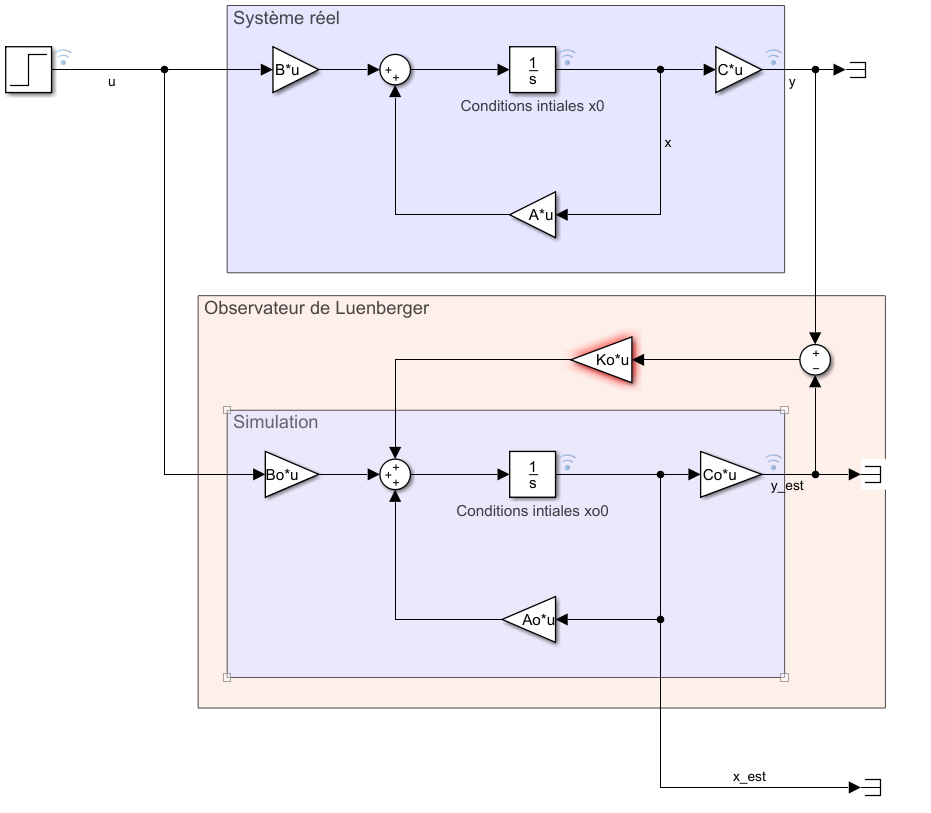


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\hat{x} =A\hat{x} +\textrm{Bu}+K_o \left(y-\hat{y} \right)\\
\hat{y} =C\hat{x} 
\end{array}$$
 

ou encore :


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\hat{x} =\left({A-K}_o C\right)\hat{x} +\left\lbrack \begin{array}{cc}
B & K_o 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack \\
\hat{y} =C\hat{x} 
\end{array}$$
 

En étudiant l'erreur d'observation $e=x-\hat{x}$ :


$$\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=\textrm{Ax}+\textrm{Bu}-A\hat{x} -\textrm{Bu}-K_o \left(y-\hat{y} \right)$$



$$\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=A\left(x-\hat{x} \right)-K_o \left(y-\hat{y} \right)$$



$$\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=A\left(x-\hat{x} \right)-K_o C\left(x-\hat{x} \right)$$



$$\dot{e} =\left(A-K_o C\right)e$$


Cette équation converge selon les valeurs propres de la matrice $\left(A-K_o C\right)$. 

#### **Lemme de Kalman : **

Les propriétés suivantes sont équivalentes :

- l'état du système est observable

- à partir des mesures, de l'entrée et de leurs dérivées successives, on peut déduire la condition initiale et la trajectoire passée du vecteur d'état.

- la condition de Kalman est vérifiée : $\textrm{rank}\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\vdots \\
{\textrm{CA}}^{n-1} 
\end{array}\right\rbrack =n$

- $\forall \;\left\lbrace \lambda {\;}_{1\;} ,\ldotp \ldotp \ldotp ,\lambda_{n\;} \right\rbrace \in \;$$\mathbb{C}^n$ $\exists K_o$ s.t.  $\textrm{eig}\left(A-K_o C\right)=$$\left\lbrace \lambda {\;}_{1\;} ,\cdots \;,\lambda_{n\;} \right\rbrace$

Si la paire $\left(A,C\right)$ est observable, on peut procéder à un palcement de pôles, i.e.

Matrice_observabilite = obsv(A,C)

Matrice_observabilite =      0     1
     1     0


rang = rank (Matrice_observabilite)

rang = 2


if (rank(obsv(A,C))==size(A,1))
    fprintf('Le système est observable')
else
    fprintf('Le système n''est observable')
end

Le système est observable

#### Réglage de l'observateur

Les propriétés de convergence sont données par les valeurs propres de la matrice $\left(A-K_o C\right)$. On va souvent choisir des valeurs pour que l'erreur converge plus vite que le système (sinon l'estimation sera obsolète quand elle sera juste). 

% en matlab, on transpose le problème pour le formuler comme un problème de
% commande

Ko = place(A',C',[-3 -4])'; %% A' = transpose(A) Attention à la transpose à la fin de la ligne


On choisi ici un temps de convergence d'une seconde.

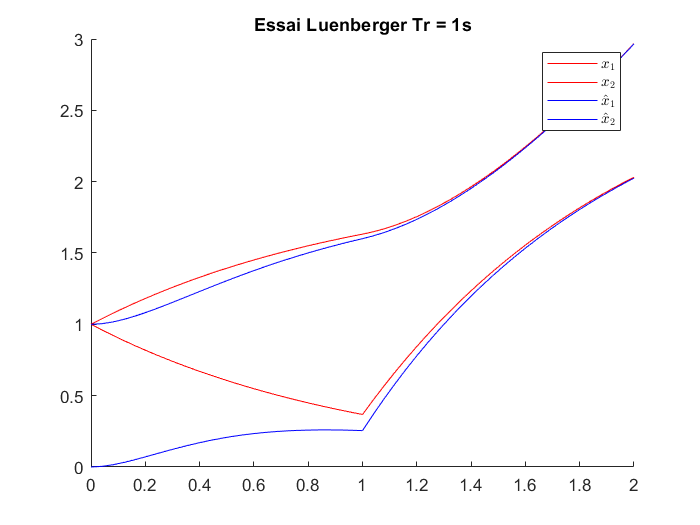

x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 1];

figure, clf, hold all

out = sim('Observateur_step2.slx');
plot(out.logsout.find('x').Values,'r')
plot(out.logsout.find('x_est').Values,'b')
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')
title('Essai Luenberger Tr = 1s')

On constate la convergence de l'état de l'observateur vers la valeur de l'état réel. On peut donc utiliser cette estimation pour remplacer l'état réel dans un retour d'état par exemple. 

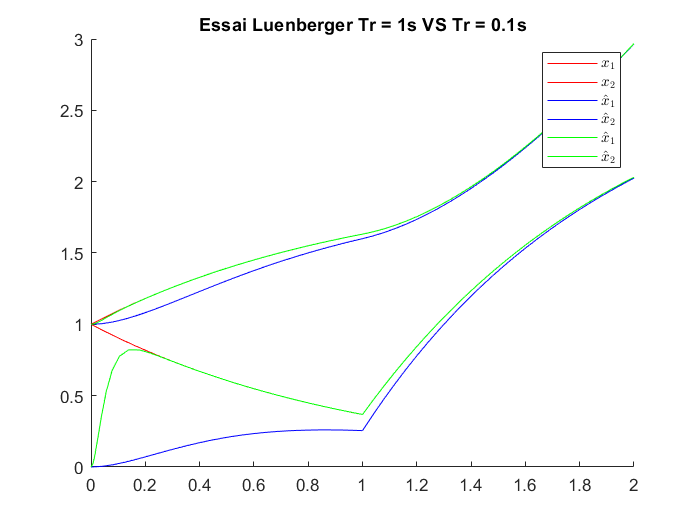

% en matlab, on transpose le problème pour le formuler comme un problème de
% commande

x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 1];

Ko = place(Ao',Co',[-3 -4])'; %% A' = transpose(A) Attention à la transpose à la fin de la ligne
out = sim('Observateur_step2.slx');

Ko = place(Ao',Co',[-30 -40])'; %% A' = transpose(A) Attention à la transpose à la fin de la ligne
out_rapide = sim('Observateur_step2.slx');

figure, clf, hold all

plot(out.logsout.find('x').Values,'r')
plot(out.logsout.find('x_est').Values,'b')
plot(out_rapide.logsout.find('x_est').Values,'g')
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')
title('Essai Luenberger Tr = 1s VS Tr = 0.1s')

En plaçant augmentant la norme des pôles, on obtient une convergence plus rapide (ici x10).

#### Limites de réglage

- Bien qu'il n'y ait pas de limite physique à ce que peut faire l'observateur (il est purement artificiel), il faut garder en tête que plus l'observateur est rapide, plus le calculateur qui devra l'executer devra être puissant. 

- Plus les valeurs propres sont 'déplacées' de leur position d'origine, plus les gains sont grands. Comme ces gains multiplient les mesures et que ces mesures sont potentiellement bruitées, on risque d'amplifier les bruits.

## Utilisation de l'observateur

- on utilise les observateurs pour réaliser des retours d'états

- on utilise les observateurs pour filtrer ce que les mesures donnent

- on utilise les observateurs pour le diagnostic et l'estimation de paramètres

### Retour d'état

Si l'estimation de l'état converge suffisament 'bien' vers l'état réel, alors on peut exploiter cette estimation pour remplacer l'utilisaiton de l'état dans les lois de commande. 

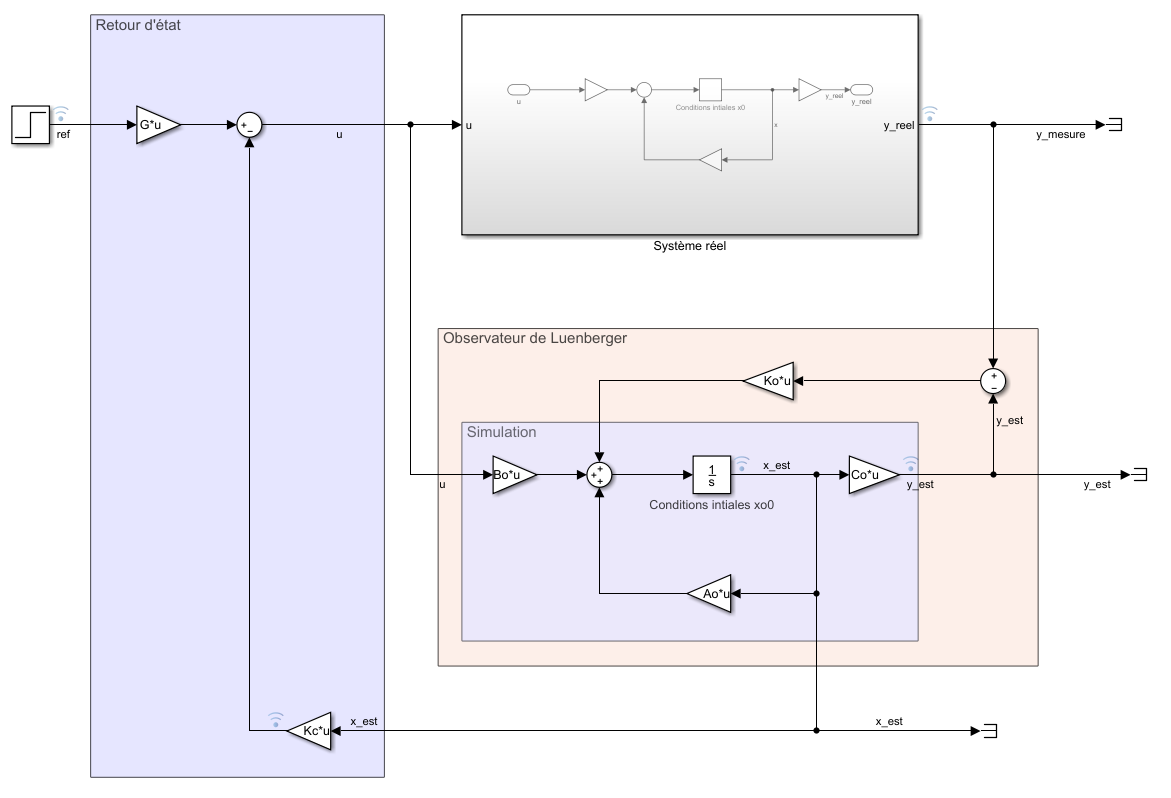

Ainsi, la commande par retour d'état devient:

$u=\textrm{Gr}-K_{c\;} \hat{x}$ à la place de $u=\textrm{Gr}-K_{c\;} x$

La boucle fermée composée du système, de l'observateur et de la loi de commande s'écrit dans ce cas :


$$\left\lbrace \begin{array}{c}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}\\
u=\textrm{Gr}-K_{c\;} \hat{x} \\
\frac{d}{\textrm{dt}}\hat{x} =\left({A-K}_o C\right)\hat{x} +\left\lbrack \begin{array}{cc}
B & K_o 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack \\
\hat{y} =C\hat{x} 
\end{array}\right.$$


Si on introduit les équations de l'erreur d'observation :


$$\left\lbrace \begin{array}{c}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
u=\textrm{Gr}-K_{c\;} \hat{x} =\textrm{Gr}-K_{c\;} x+K_{c\;} \left(x-\hat{x} \right)\;\\
\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=\left(A-K_o C\right)\left(x-\hat{x} \right)
\end{array}\right.$$



$$\frac{d}{\textrm{dt}}\left(\begin{array}{c}
x\\
x-\hat{x} 
\end{array}\right)=\left\lbrack \begin{array}{cc}
A-{\textrm{BK}}_c  & {\textrm{BK}}_c \\
0 & {A-K}_o C
\end{array}\right\rbrack \left(\begin{array}{c}
x\\
\hat{x} 
\end{array}\right)+\left\lbrack \begin{array}{c}
\textrm{BG}\\
0
\end{array}\right\rbrack r\left(t\right)$$


#### Principe de séparation : 

Le système étant triangulaire, ces valeurs propres sont les valeurs propres de $A-{\textrm{BK}}_c$ complétée par celles de ${A-K}_o C$. Les propriétés globale sur système en boucle fermée sont donc celle du cas de la boucle fermée sans observateur + celles de l'observateur seul. On appelle cela le principe de séparation : on peut régler la commande et l'observateur séparement.

#### Exemple

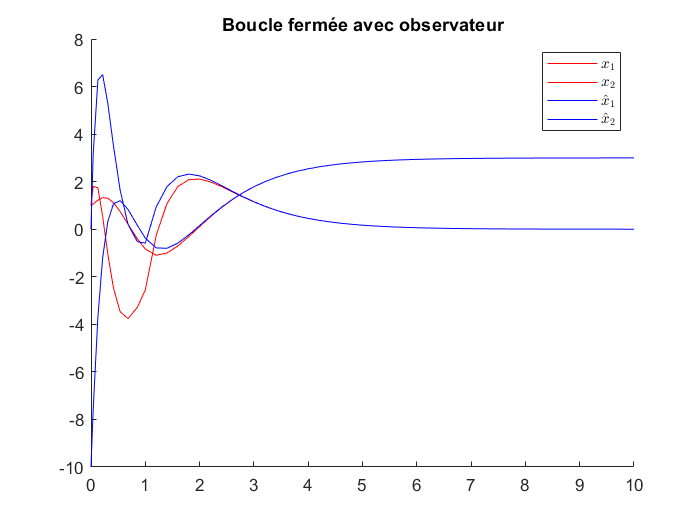

Kc = place(A,B,[-1 -3]);
G = -(C*(A-B*Kc)^-1*B)^-1;

Ko = place(Ao',Co',[-3 -4])';

x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 -10];

figure, clf, hold all
out = sim('Observateur_step2_Retour_etat.slx',10);
plot(out.logsout.find('x').Values,'r')
plot(out.logsout.find('x_est').Values,'b')
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')
title('Boucle fermée avec observateur')

On remarque deux périodes : la première où l'observateur n'a pas convergé et la commande est 'maladroite' puis la convergence du système quand l'observateur est suffisament proche de la valeur réelle de l'état du système. Ceci illustre le fait que l'oservateur doit être très rapide par rapport à la vitesse de convergence du système en boucle fermée. On choisi souvent 5x plus rapide.

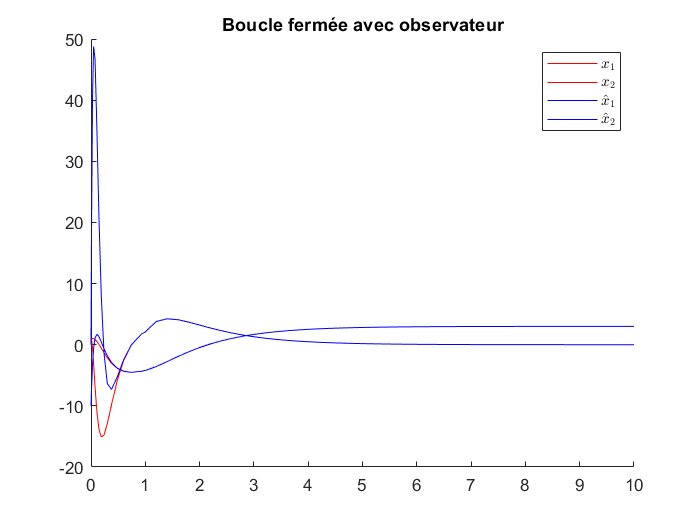

Kc = place(A,B,[-1 -3]);
G = -(C*(A-B*Kc)^-1*B)^-1;

Ko = place(Ao',Co',[-15 -16])';

x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 -10];

figure, clf, hold all
out = sim('Observateur_step2_Retour_etat.slx',10);
plot(out.logsout.find('x').Values,'r')
plot(out.logsout.find('x_est').Values,'b')
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')
title('Boucle fermée avec observateur')

### Cas fitrage de bruit

On s'interesse à l'effet des bruits de mesure :

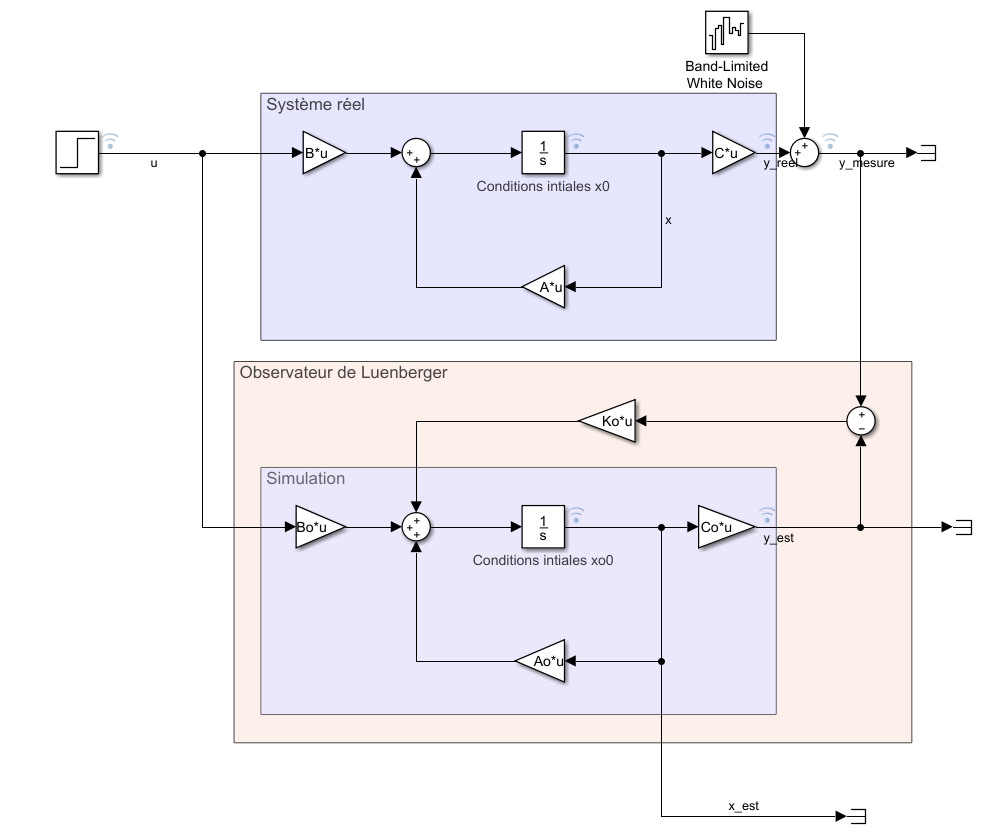

Dans ce cas nous avons :


$$\left\lbrace \begin{array}{c}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}+n\left(t\right)\\
\frac{d}{\textrm{dt}}\hat{x} =A\hat{x} +\textrm{Bu}+K_o \left(y-\hat{y} \right)
\end{array}\right.$$


En étudiant l'erreur d'observation $e=x-\hat{x}$ :


$$\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=\textrm{Ax}+\textrm{Bu}-A\hat{x} -\textrm{Bu}-K_o \left(y-\hat{y} \right)$$



$$\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=A\left(x-\hat{x} \right)-K_o \left(y-\hat{y} \right)$$



$$\frac{d}{\textrm{dt}}\left(x-\hat{x} \right)=A\left(x-\hat{x} \right)-K_o C\left(x-\hat{x} \right)-K_o n\left(t\right)$$



$$\dot{e} =\left(A-K_o C\right)e-K_o n\left(t\right)$$


On constate que la stabilité n'est pas altérée mais l'erreur est pertubée par le bruit.

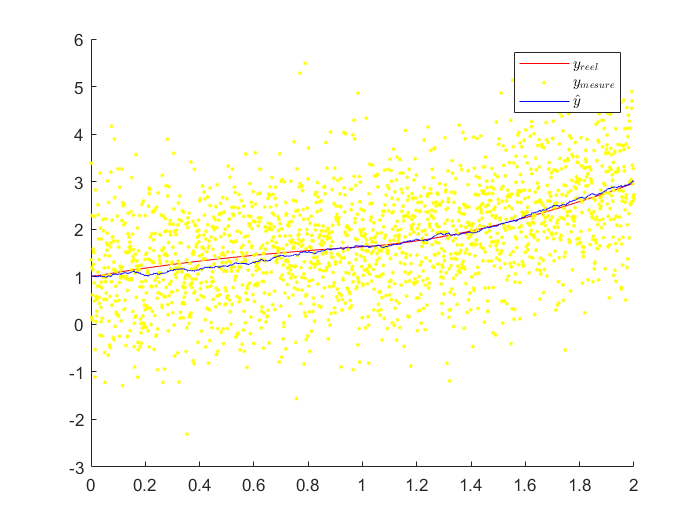

% en matlab, on transpose le problème pour le formuler comme un problème de
% commande

Ko = place(Ao',Co',[-3 -4])'; %% A' = transpose(A) Attention à la transpose à la fin de la ligne
 
x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 1];

figure, clf, hold all

out = sim('Observateur_step2_bruits.slx');
plot(out.logsout.find('y_reel').Values,'r')
plot(out.logsout.find('y_mesure').Values,'y.')
plot(out.logsout.find('y_est').Values,'b')
legend('$$y_{reel}$$','$$y_{mesure}$$','$$\hat{y}$$','Interpreter','latex')


ecart_type_erreur_mesure = std(out.logsout.find('y_mesure').Values-out.logsout.find('y_reel').Values)

ecart_type_erreur_mesure = 0.9989

ecart_type_erreur_estimation = std(out.logsout.find('y_est').Values-out.logsout.find('y_reel').Values)

ecart_type_erreur_estimation = 0.0742

La mesure issue du capteur est filtrée à l'aide de l'observateur. L'écart-type est plus faible lorque l'on passe par l'observateur. 

On peut également étudier la réponse fréquencielle du système erreur vis-à-vis du bruit de mesure :

Ko = place(Ao',Co',[-3 -4])';
sys_e_lent = ss(Ao-Ko*Co,Ko,eye(2),0);
Ko = place(Ao',Co',[-30 -40])';
sys_e_rapide = ss(Ao-Ko*Co,Ko,eye(2),0);
bodemag(sys_e_lent,sys_e_rapide);

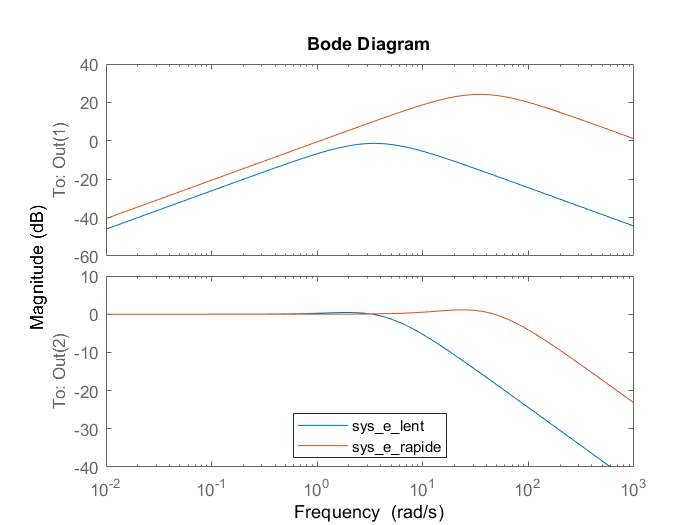

legend('location','best')

On remarque que plus l'observateur est rapide, plus il est sensible aux bruits hautes fréquences.

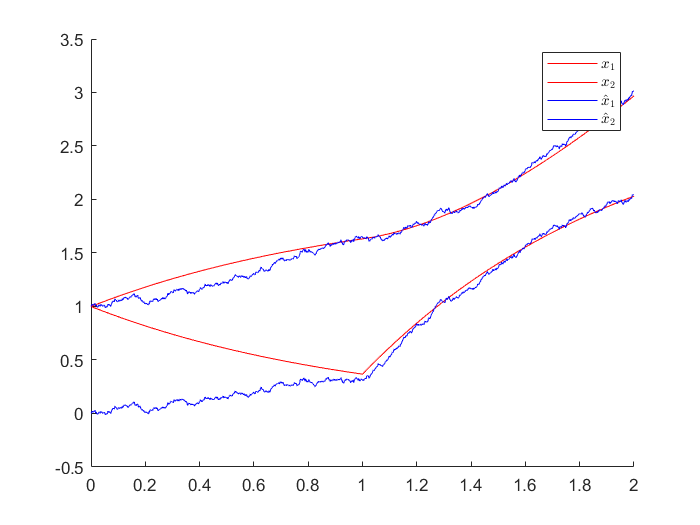

figure, clf, hold all

plot(out.logsout.find('x').Values,'r')
plot(out.logsout.find('x_est').Values,'b')
legend('$$x_1$$','$$x_2$$','$$\hat{x}_1$$','$$\hat{x}_2$$','Interpreter','latex')

On constate que l'estimation d'état est dégradée mais semble correcte et exploitable pour commander le système.

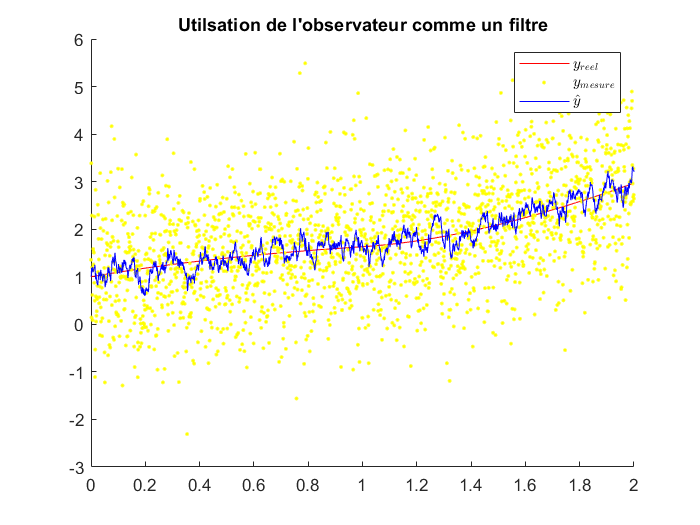

% en matlab, on transpose le problème pour le formuler comme un problème de
% commande

Ko = place(Ao',Co',[-30 -40])'; %% A' = transpose(A) Attention à la transpose à la fin de la ligne
 
x0  =   [1 1];
u0  =   0;
uf  =   3;
xo0 =   [0 1];

figure, clf, hold all

out = sim('Observateur_step2_bruits.slx');
plot(out.logsout.find('y_reel').Values,'r')
plot(out.logsout.find('y_mesure').Values,'y.')
plot(out.logsout.find('y_est').Values,'b')
legend('$$y_{reel}$$','$$y_{mesure}$$','$$\hat{y}$$','Interpreter','latex')
title('Utilsation de l''observateur comme un filtre')


ecart_type_erreur_mesure = std(out.logsout.find('y_mesure').Values-out.logsout.find('y_reel').Values)

ecart_type_erreur_mesure = 0.9982

ecart_type_erreur_estimation = std(out.logsout.find('y_est').Values-out.logsout.find('y_reel').Values)

ecart_type_erreur_estimation = 0.1894

Si on augmente la rapidité de la converge on augmente aussi la sensibilité au bruit. Ici on continue tout de même à améliorer les performances du capteur mais cela peut avoir des conséquences dramatiques sur l'estimation d'état (ici l'estimation de l'état $x_1$ semble inexploitable).

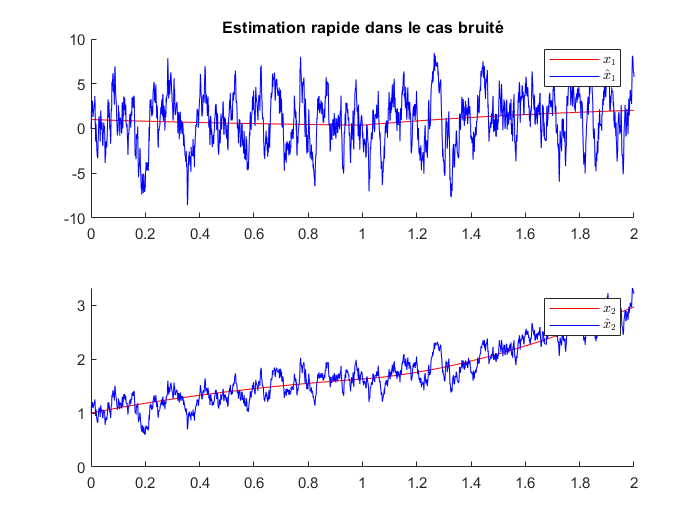

figure, clf
x = out.logsout.find('x').Values; %timeseries of x
x_est = out.logsout.find('x_est').Values; %timeseries of x_est
subplot(2,1,1),hold all
plot(x.Time,x.Data(:,1),'r');
plot(x_est.Time,x_est.Data(:,1),'b');
legend('$$x_1$$','$$\hat{x}_1$$','Interpreter','latex')
title('Estimation rapide dans le cas bruité')
subplot(2,1,2),hold all
plot(x.Time,x.Data(:,2),'r');
plot(x_est.Time,x_est.Data(:,2),'b');
legend('$$x_2$$','$$\hat{x}_2$$','Interpreter','latex')

### Utilisation pour le diagnostic et l'estimation de parametres

Cet usage ne sera pas couvert dans ce module. Ce sujet est couvert par le module 'estimation for engineers'.

## Autres méthodes de réglage

Il existes d'autres méthodes de réglage que le placement de pôle mais elles ne seront probablement pas abordés dans ce cours. Elles changent principalement le moyen s'exprimer les performances souhaitées :

- LQR

- Filtre de Kalman

- Synthèse LMI

- Synthèse $H_{\infty }$

- ...